load C:\class\coursefiles\mlbe\electricity\electricity.mat

% extract all the June and October data into vairables

june = [ price(6,1:26); usage(6,1:26) ]

june =    1.0e+11 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.7390    0.8095    0.7091    0.7658    0.8409    0.8423    0.9095    0.8357    0.9849    0.9594    1.0399    0.9941    1.0717    1.0129    1.1234    1.1663    1.1882    1.1742    1.2138    1.1440    1.2750    1.2598    1.2293    1.1798    1.1805    1.1993


october = [ price(8,1:26); usage(8,1:26) ]

october =    1.0e+11 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.8856    0.9297    0.8851    1.0219    0.9675    1.1489    1.0556    1.0696    1.2033    1.2403    1.2370    1.2921    1.3433    1.3447    1.2642    1.4690    1.5006    1.5010    1.3846    1.3822    1.5405    1.5374    1.4794    1.3807    1.3583    1.4409


% wtf ^ ???

junePrice = price(6,1:26)

junePrice =     8.1002    8.3193    8.6122    8.7415    8.7705    8.7227    8.6523    8.9141    8.5258    8.4259    8.5555    9.0677    8.7333    9.2516    9.2941    9.7892   10.8477   11.0877   11.7709   11.8122   11.9132   11.9695   12.0903   12.5386   12.9918   12.9339


juneUsage = usage(6,1:26)

juneUsage =    1.0e+11 *

    0.7390    0.8095    0.7091    0.7658    0.8409    0.8423    0.9095    0.8357    0.9849    0.9594    1.0399    0.9941    1.0717    1.0129    1.1234    1.1663    1.1882    1.1742    1.2138    1.1440    1.2750    1.2598    1.2293    1.1798    1.1805    1.1993



octoberPrice = price(8,1:26)

octoberPrice =     8.2392    8.4139    8.5624    8.7340    8.8446    8.7820    8.8667    8.7978    8.5688    8.4211    8.6226    9.0131    8.7170    9.2176    9.5017    9.9294   10.9356   11.0734   12.0874   11.9404   12.0277   12.0871   12.1734   12.5256   13.0370   12.9343


octoberUsage = usage(8,1:26)

octoberUsage =    1.0e+11 *

    0.8856    0.9297    0.8851    1.0219    0.9675    1.1489    1.0556    1.0696    1.2033    1.2403    1.2370    1.2921    1.3433    1.3447    1.2642    1.4690    1.5006    1.5010    1.3846    1.3822    1.5405    1.5374    1.4794    1.3807    1.3583    1.4409


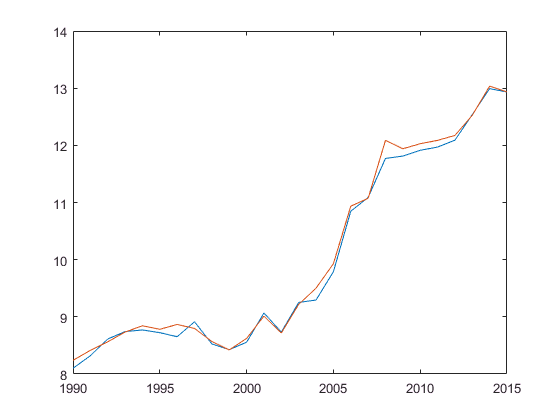


plot(yr,junePrice)
hold on
plot(yr,octoberPrice)
hold off

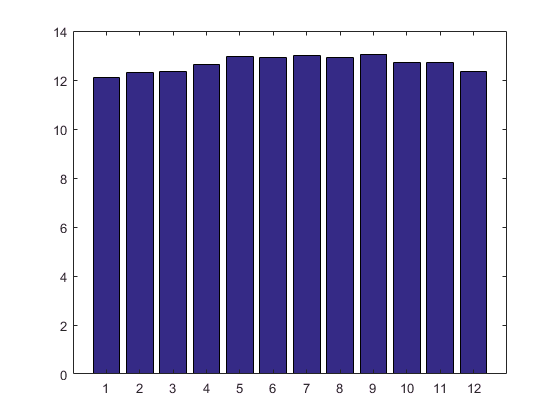


price2015 = price(:,end);
bar(mth,price2015)
xlim([0 13])

## cent/kWh, dollars/MWh

price = price*10;

% dot star = element by element multiplication
revenue = price.*usage;

whos price usage revenue

  Name          Size            Bytes  Class     Attributes

  price        12x26             2496  double              
  revenue      12x26             2496  double              
  usage        12x26             2496  double              



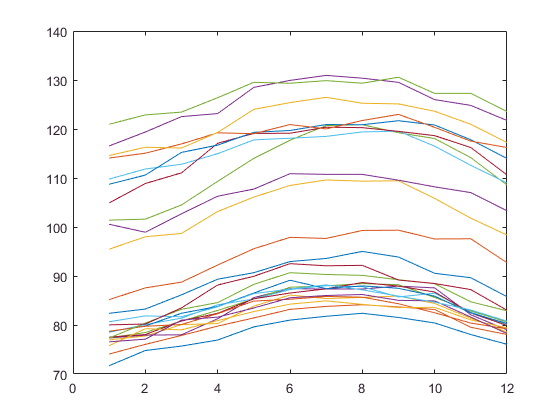

plot(mth,price)

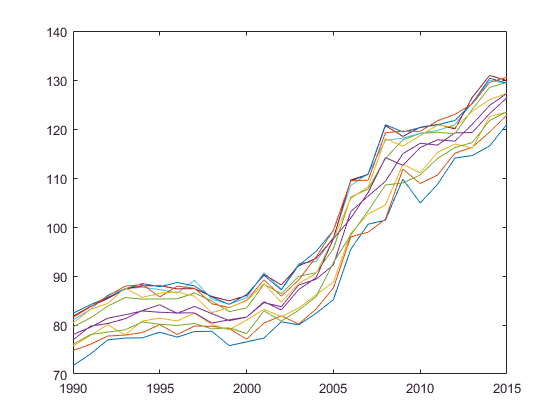

plot(yr,price')

priceInflation = price(:,end)./price(:,1)

priceInflation =     1.6873
    1.6429
    1.6308
    1.6429
    1.6269
    1.5967
    1.5881
    1.5698
    1.6013
    1.5827



price2015 = price.*dollar2015

price2015 =   130.0575  128.8972  130.0245  126.9095  123.7403  122.1212  117.1462  116.1572  114.4598  107.8228  105.3892  103.5225  106.2872  103.1029  103.3859  103.3819  112.2428  114.9503  111.6344  121.2781  114.0437  114.5606  117.7590  116.5743  116.6845  120.9735
  135.6709  132.3471  131.3461  127.8895  125.4738  124.5662  117.9359  117.8249  115.9428  112.7485  106.1433  107.6164  107.8690  103.3148  104.4737  106.2882  115.2274  113.0862  111.8535  123.5538  118.3468  116.5366  118.7774  118.3005  119.5278  122.8725
  137.3190  135.4927  135.2615  127.9877  129.2279  126.5919  122.1216  121.6769  116.4584  112.4227  111.4858  111.3727  107.6221  107.5564  108.1157  107.7116  116.0268  117.3904  115.0426  124.6237  120.7131  121.4146  120.7299  118.1362  122.6726  123.4491
  139.5516  138.8198  135.6537  133.3596  132.6890  130.8246  124.4963  123.7267  119.6906  115.0881  112.3400  113.2124  110.3283  113.5852  112.1198  111.9520  121.2883  121.4896  120.3470  127.0144  127

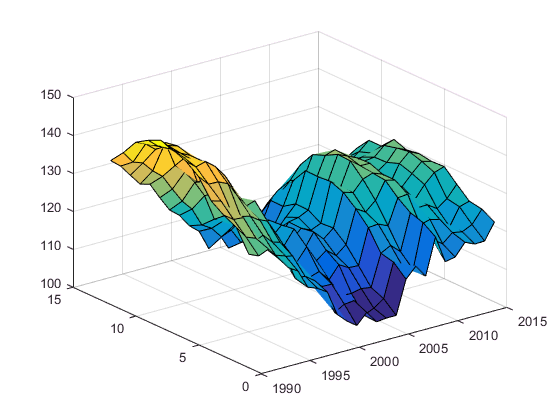


surf(yr,mth,price2015)

w = dollar2015/sum(dollar2015)

w =     0.0527    0.0506    0.0491    0.0477    0.0465    0.0452    0.0439    0.0429    0.0423    0.0413    0.0400    0.0389    0.0383    0.0374    0.0365    0.0353    0.0342    0.0332    0.0320    0.0321    0.0316    0.0306    0.0300    0.0296    0.0291    0.0291


sum(w)

ans = 1.0000


avgWithInflation = price*w'

avgWithInflation =    87.2765
   88.8002
   90.6337
   93.0554
   95.7230
   97.4567
   97.8580
   98.0576
   97.4682
   96.0336


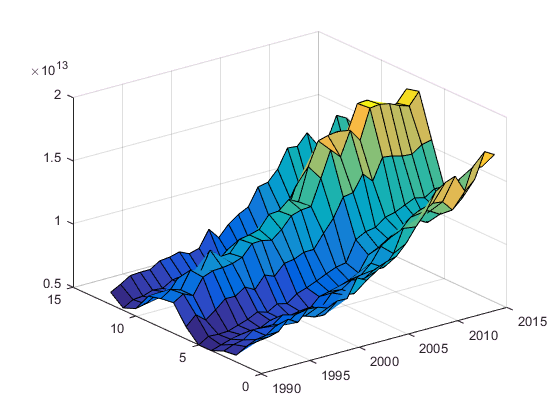

surf(yr,mth,revenue)

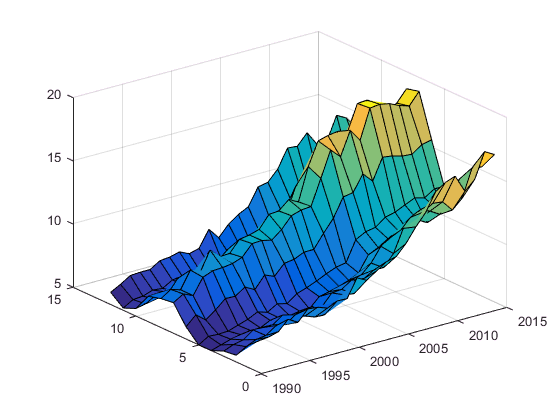


revTrillions = round(revenue/1e12,2);

surf(yr,mth,revTrillions)

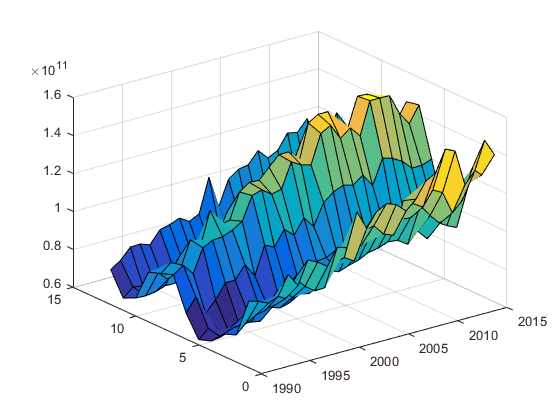

% Analyze usage
surf(yr,mth,usage)


m = mean(usage)

m =    1.0e+11 *

    0.7700    0.7962    0.7799    0.8290    0.8404    0.8688    0.9021    0.8966    0.9418    0.9541    0.9937    1.0013    1.0543    1.0632    1.0767    1.1327    1.1263    1.1602    1.1506    1.1373    1.2048    1.1857    1.1454    1.1623    1.1727    1.1666


size(m)

ans =      1    26


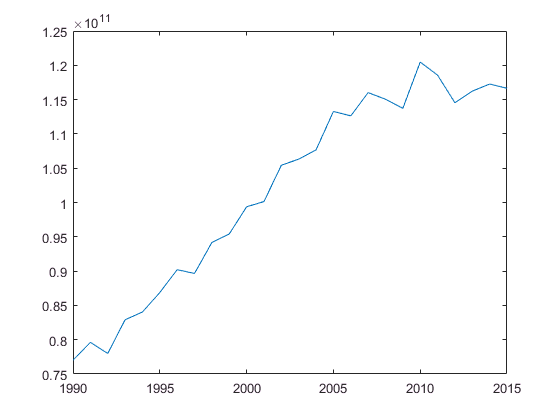


plot(yr,m)


monthly = mean(usage,2)    % the 2 means to operate accrose the rows, not the columns

monthly =    1.0e+11 *

    1.1859
    1.0218
    0.9480
    0.8141
    0.8348
    1.0326
    1.2611
    1.2640
    1.0807
    0.8797


size(monthly)

ans =     12     1


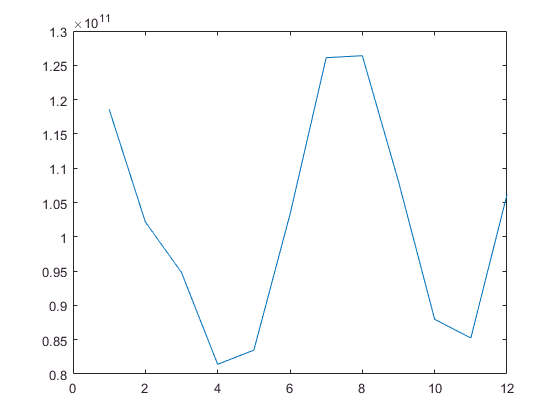


plot(mth,monthly)

du = diff(usage)    % change over time of the columns

du =    1.0e+10 *

   -2.0922   -1.4411   -0.9306   -1.0368   -1.4142   -0.9874   -1.2493   -1.5902   -1.5995   -2.4537   -1.1050   -2.7188   -2.0299   -1.3335   -1.4657   -1.8621   -1.5908   -0.3822   -1.4815   -2.1017   -2.4660   -2.4952   -1.7906   -1.8671   -1.8036   -1.3754
   -0.2597   -0.5581   -0.8412   -0.0371   -0.9800   -0.7214   -0.9081   -0.8838   -0.0590    0.2759   -1.3937   -0.7073   -0.1274   -1.1376   -1.3517   -0.2602    0.0444   -1.5769   -1.1391   -0.8711   -1.1050   -1.5188   -0.8614   -0.1017   -1.4243   -0.6912
   -0.6711   -0.7975   -0.5304   -1.3351   -1.0391   -1.0880   -1.2420   -0.8681   -1.1821   -1.2162   -0.8427   -1.0351   -0.9911   -1.6113   -1.3570   -1.7316   -1.5581   -1.5413   -1.4997   -1.4870   -2.3744   -1.1220   -1.1258   -1.6556   -2.1943   -2.6939
   -0.2310    0.1379   -0.3668   -0.5820   -0.2336    0.1518   -0.0070   -0.1967    0.3339   -0.0109    0.7139   -0.0723    0.1911    0.4356    0.5221    0.0635    0.4626    0.6107    0.0080    0.26

size(du)

ans =     11    26



dm = diff(usage,1,2)    % the 1 is the oder of subtraction

dm =    1.0e+10 *

   -0.1566   -0.2382    0.2320    1.0032   -0.7272    1.2059   -0.2445   -0.3617    0.8652   -0.1590    1.7455   -1.0174    0.7381    0.2849   -0.1834   -0.4869    0.4867    0.8082    0.2860    1.1271   -0.2438   -1.9180    0.5903    1.4727   -0.8980
    0.4946    0.2722    0.1259    0.6258   -0.3004    0.9439   -0.5853   -0.3710    0.0109    1.1898    0.1316   -0.3285    1.4344    0.1527   -0.5797   -0.2156    1.6953   -0.2911   -0.3341    0.7628   -0.2730   -1.2135    0.5139    1.5361   -0.4698
    0.1961   -0.0109    0.9300   -0.3170   -0.0419    0.7572   -0.5610    0.4538    0.3459   -0.4799    0.8180    0.2514    0.4243   -0.0614    0.5118    0.0890    0.0740    0.1468   -0.0661    0.5289   -0.6868   -0.5560    1.2735    0.2136    0.2633
    0.0697    0.2562    0.1253   -0.0210   -0.0908    0.6032   -0.1871    0.1398    0.3117   -0.1063    0.6256    0.2954   -0.1959    0.1929    0.1372    0.2625    0.0908    0.1884   -0.0535   -0.3585    0.5655   -0.5598    0.74

size(dm)

ans =     12    25



bar(mth,monthly)
axis tight

MM = {'Jan', 'Feb', 'Mar', 'Apr', 'May', 'Jun', 'Jul', 'Aug', ...
    'Sep', 'Oct', 'Nov', 'Dec'}

MM =     'Jan'    'Feb'    'Mar'    'Apr'    'May'    'Jun'    'Jul'    'Aug'    'Sep'    'Oct'    'Nov'    'Dec'


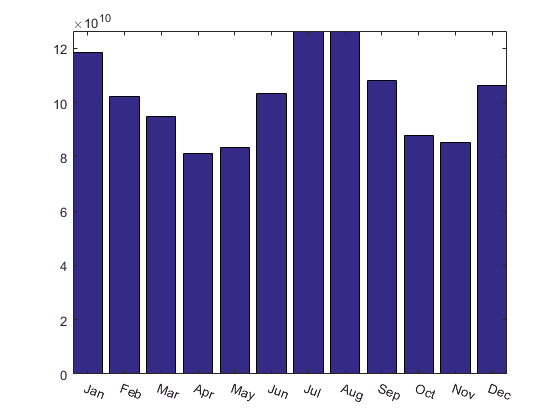


xticklabels(MM)
xtickangle(340)

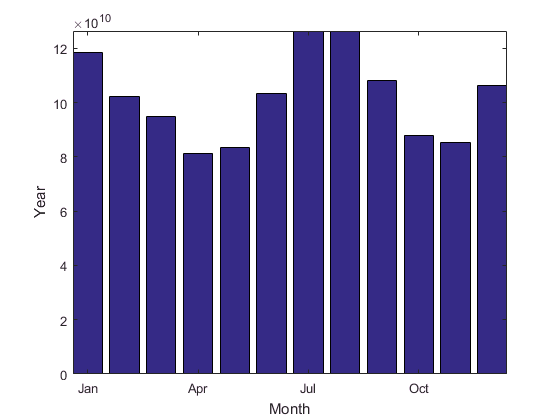


bar(mth, monthly)
axis tight
Q = {'Jan', 'Apr', 'Jul', 'Oct'};
xticks(1:3:12)
xticklabels(Q)
xlabel('Month')
ylabel('Year')

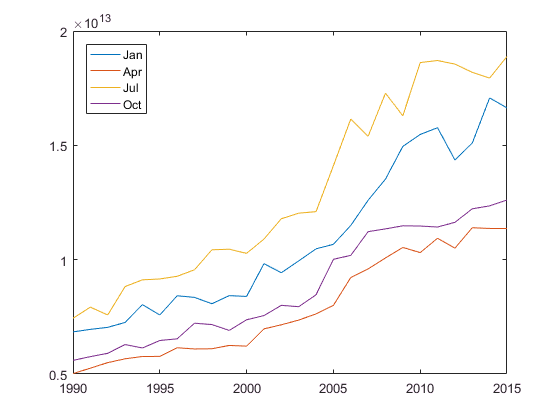



firstmonth= revenue(1:3:12,:);
plot(yr,firstmonth)
Q = {'Jan', 'Apr', 'Jul', 'Oct', 'Dec'};
legend(Q,'Location','northwest')

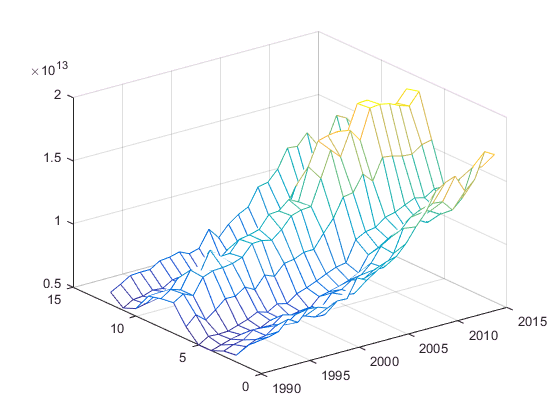

mesh(yr,mth,revenue)

% page 5-16


A = [1 2 3; 4 5 6; 7 8 9; 10 11 12]

A =      1     2     3
     4     5     6
     7     8     9
    10    11    12



A(3,3)

ans = 9

A(3)

ans = 7

A(11)

ans = 9


B = reshape(A,6,2)

B =      1     8
     4    11
     7     3
    10     6
     2     9
     5    12



B = reshape(A,6,[])

B =      1     8
     4    11
     7     3
    10     6
     2     9
     5    12


priceVec = reshape(price,[],1)

priceVec =    71.6965
   74.7910
   75.6996
   76.9303
   79.6173
   81.0016
   81.7759
   82.3921
   81.5390
   80.4163


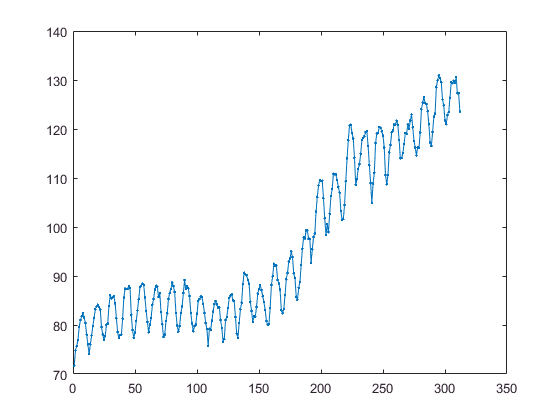

plot(priceVec,'.-')